# MXB201 Exercises 3

## Theory

T1.  Let $A \in \mathbb{R}^{m \times n}$ have full column rank.  We know that the orthogonal projector onto $A$'s column space is given by $P = A(A^TA)^{-1} A^T$.  Now, substitute $A = QR$ into $P$, where $Q$ and $R$ form the QR decomposition of $A$.  Show that the orthogonal projector reduces simply to $P = QQ^T$.

## Practice

P1.

(i) Use the Gram-Schmidt process to find orthonormal bases for the four fundamental subspaces of the matrix $A$ below.  This is the matrix from Exercises 2 P2.

A = sym([3 1 -3 ; 3 2 0 ; 2 1 -1])

$$A = \left(\begin{array}{ccc} 3 & 1 & -3\\ 3 & 2 & 0\\ 2 & 1 & -1 \end{array}\right)$$

[Q, R] = qr(A)

$$Q = \left(\begin{array}{ccc} \frac{3\,\sqrt{22}}{22} & -\frac{\sqrt{2}}{2} & \frac{\sqrt{11}}{11}\\ \frac{3\,\sqrt{22}}{22} & \frac{\sqrt{2}}{2} & \frac{\sqrt{11}}{11}\\ \frac{\sqrt{22}}{11} & 0 & -\frac{3\,\sqrt{11}}{11} \end{array}\right)$$

$$R = \left(\begin{array}{ccc} \sqrt{22} & \frac{\sqrt{22}}{2} & -\frac{\sqrt{22}}{2}\\ 0 & \frac{\sqrt{2}}{2} & \frac{3\,\sqrt{2}}{2}\\ 0 & 0 & 0 \end{array}\right)$$

[Q1, R1] = qr(A')

$$Q1 = \left(\begin{array}{ccc} \frac{3\,\sqrt{19}}{19} & \frac{4\,\sqrt{14}\,\sqrt{19}}{133} & \frac{\sqrt{2}\,\sqrt{7}}{7}\\ \frac{\sqrt{19}}{19} & \frac{9\,\sqrt{14}\,\sqrt{19}}{266} & -\frac{3\,\sqrt{2}\,\sqrt{7}}{14}\\ -\frac{3\,\sqrt{19}}{19} & \frac{11\,\sqrt{14}\,\sqrt{19}}{266} & \frac{\sqrt{2}\,\sqrt{7}}{14} \end{array}\right)$$

$$R1 = \left(\begin{array}{ccc} \sqrt{19} & \frac{11\,\sqrt{19}}{19} & \frac{10\,\sqrt{19}}{19}\\ 0 & \frac{3\,\sqrt{14}\,\sqrt{19}}{19} & \frac{\sqrt{14}\,\sqrt{19}}{19}\\ 0 & 0 & 0 \end{array}\right)$$

(ii) Use these orthonormal bases to calculate orthogonal projectors onto the four fundamental subspaces, and confirm they come out the same as those you found in Exercises 2 P2.

P_C = A(:, 1:2) * inv(A(:, 1:2)' * A(:, 1:2)) * A(:, 1:2)'

$$P\_C = \left(\begin{array}{ccc} \frac{10}{11} & -\frac{1}{11} & \frac{3}{11}\\ -\frac{1}{11} & \frac{10}{11} & \frac{3}{11}\\ \frac{3}{11} & \frac{3}{11} & \frac{2}{11} \end{array}\right)$$

Q_C = Q(:, 1:2) * inv(Q(:, 1:2)' * Q(:, 1:2)) * Q(:, 1:2)'

$$Q\_C = \left(\begin{array}{ccc} \frac{10}{11} & -\frac{1}{11} & \frac{3}{11}\\ -\frac{1}{11} & \frac{10}{11} & \frac{3}{11}\\ \frac{3}{11} & \frac{3}{11} & \frac{2}{11} \end{array}\right)$$

(iii) Assemble the bases for the row space and null space into a complete orthonormal basis for $R^3$.

(iv) Assemble the bases for the column space and left null space into a complete orthonormal basis for $R^3$.

P2. Anton's Exercise Set 6.3.

Questions 1, 5, 7, 11, 15, 17, 19, 21, 23, 25, 27, 29, 31, 33, 35, 49

## Exploration

E1.  Suppose you have a matrix $A$ of full column rank, and you apply the Gram-Schmidt process as usual to generate the matrix $Q$, which has the same column space as $A$ but with orthonormal columns.  Later, you realise you really want the QR decomposition of $A$, so you also need the matrix $R$.  Alas, you forgot to record your working when applying the Gram-Schmidt process!  Is the situation hopless?  Or is there a way to recover the matrix $R$ you need for the QR decomposition from $A$ and $Q$ without having to start the process all over again?  If you think you have a method, experiment with a small, made-up example to see if it works.

E2.  Let $A$ be any random $5 \times 3$ matrix.  We'll use floating point arithmetic:

A = rand(5,3)

A =     0.4898    0.2760    0.4984
    0.4456    0.6797    0.9597
    0.6463    0.6551    0.3404
    0.7094    0.1626    0.5853
    0.7547    0.1190    0.2238


We know to perform a QR decomposition in MATLAB we use the syntax:

[Q,R] = qr(A, 0)  % with comma zero

Q =    -0.3526   -0.0080    0.2163
   -0.3208   -0.6701    0.5218
   -0.4654   -0.4604   -0.6887
   -0.5108    0.3551    0.3932
   -0.5434    0.4613   -0.2283


R =    -1.3888   -0.7680   -1.0626
         0   -0.6466   -0.4927
         0         0    0.5532


As expected, $Q$ is the same size as $A$, and $R$ is square upper triangular.

What then, does the command

[Q,R] = qr(A)  % no comma zero

Q =    -0.3526   -0.0080    0.2163   -0.7078   -0.5725
   -0.3208   -0.6701    0.5218   -0.0121    0.4191
   -0.4654   -0.4604   -0.6887    0.2117   -0.2289
   -0.5108    0.3551    0.3932    0.6093   -0.2952
   -0.5434    0.4613   -0.2283   -0.2876    0.5976


R =    -1.3888   -0.7680   -1.0626
         0   -0.6466   -0.4927
         0         0    0.5532
         0         0         0
         0         0         0


Q'*Q

ans =     1.0000         0   -0.0000    0.0000    0.0000
         0    1.0000    0.0000   -0.0000         0
   -0.0000    0.0000    1.0000   -0.0000   -0.0000
    0.0000   -0.0000   -0.0000    1.0000    0.0000
    0.0000         0   -0.0000    0.0000    1.0000


produce?  In particular, what is the meaning of the "extra" columns in $Q$?  And why don't they mess up the validity of the QR decomposition $A = QR$?  Test any ideas you come up with to see if you're correct.

## Application

In this section we will use *floating point arithmetic*, since the problems are of a sufficient size to make symbolic arithmetic inefficient.

### A1 Function approximation

Suppose we want to approximate some function $f(t)$ over the interval $[a,b]$ by a polynomial of degree $n$, $P(t) = c_0 + c_1 t + \ldots + c_nt^n$.  What polynomial should we choose to get the "best possible" accuracy over the entire inverval?

One approach we might think of is to sample the function $f$ at $m$ uniformly-spaced points $t_i,\ i=1,\ldots, m$ over the interval $[a,b]$ and find the least squares polynomial through the data points we sampled.  That is, we form the overdetermined linear system $Ac = b$ given by

$\left\lbrack \begin{array}{ccccc}
1 & t_1  & {t_1 }^2  & \cdots  & {t_1 }^n \\
1 & t_2  & {t_2 }^2  & \cdots  & {t_2 }^n \\
\vdots  & \vdots  & \vdots  & \ddots  & \vdots \\
1 & t_m  & {t_m }^2  & \cdots  & {t_m }^n 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
c_0 \\
c_1 \\
\vdots \\
c_n 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
f\left(t_1 \right)\\
f\left(t_2 \right)\\
\vdots \\
f\left(t_m \right)
\end{array}\right\rbrack$,      $m \gg n$  (so $A$ is a tall matrix)

Let's try it out on an example.  Let $f(t) = e^t$ over the interval $[0,1]$, and we'll fit a polynomial of degree $n = 12$.  Suppose we sample $f$ at $m = 50$ uniformly-spaced points on $[0,1]$.

(i) Generate the coefficient matrix $A$ and right hand side vector $b$.

clear 
n = 12;
m = 50;

f = @(x) exp(x);

t = linspace(0, 1, m)';

A = zeros([m, n + 1])

A =      0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0


for i = 1:m
    for j = 1:n + 1
        A(i, j) = t(i)^(j - 1);
    end
end
A

A =    1.000000000000000                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0
   1.000000000000000   0.020408163265306   0.000416493127863   0.000008499859752   0.000000173466526   0.000000003540133   0.000000000072248   0.000000000001474   0.000000000000030   0.000000000000001   0.000000000000000   0.000000000000000   0.000000000000000
   1.000000000000000   0.040816326530612   0.001665972511454   0.000067998878019   0.000002775464409   0.000000113284262   0.000000004623847   0.000000000188728   0.000000000007703   0.000000000000314   0.000000000000013   0.000000000000001   0.000000000000000
   1.000000000000000   0.061224489795918   0.003748438150771   0.000229496213312   0.000014050788570   0.000000860252361   0.000000052668512   0.000000003224603   0.000000000197425   0.000000000012087   0.00000000

b = f(t)

b =    1.000000000000000
   1.020617833729903
   1.041660762527521
   1.063137550932278
   1.085057144189416
   1.107428671975758
   1.130261452202282
   1.153564994895108
   1.177349006156492
   1.201623392207494


(ii) Set up and solve the normal equations $A^TAc = A^T b$ to find the solution vector of coefficients $c_0$ to $c_{12}$.  Let's call the resulting polynomial ${P}^{(ii)}(t)$.

rank(A)

ans =     13


format long
c = (A' * A) \ (A' * b)

c =    0.999999993234523
   1.000002925994366
   0.499866731833642
   0.169025845863173
   0.019887195461385
   0.128044193419524
  -0.418746874259432
   0.976243264473935
  -1.519128133202752
   1.566992144515344


P_ii = @(t) polyval(flip(c), t)

P_ii = function_handle with value:
    @(t)polyval(flip(c),t)


(iii) Find the QR decomposition of $A$ (use MATLAB's `qr` function).

[Q, R] = qr(A, 0);
c_qr = R \ (Q' * b)

c_qr =    0.999999999999999
   1.000000000000025
   0.499999999998610
   0.166666666693973
   0.041666666407858
   0.008333334746753
   0.001388884051739
   0.000198423461238
   0.000024785956644
   0.000002770062202


(iv) Solve the system $Rc = Q^T b$ to find the solution vector of coefficients; use a different symbol (say, capital `C)` in MATLAB so you don't overwrite your solution from (ii).  Let's call the resulting polynomial ${P}^{(iv)}(t)$.

P_iv = @(t) polyval(flip(c_qr), t)

P_iv = function_handle with value:
    @(t)polyval(flip(c_qr),t)


(v) Mathematically, your answers for (ii) and (iv) should be identical.  But are they?  If not, which set of coefficients do you trust more?  How do you judge which are the more reliable?

norm(c - c_qr)

ans =    2.667999420454064


(vi) Produce a plot of $e^t$, ${P}^{(ii)}(t)$ and ${P}^{(iv)}(t)$over the interval $[0,1]$ on the same axes.  Can you tell them apart?

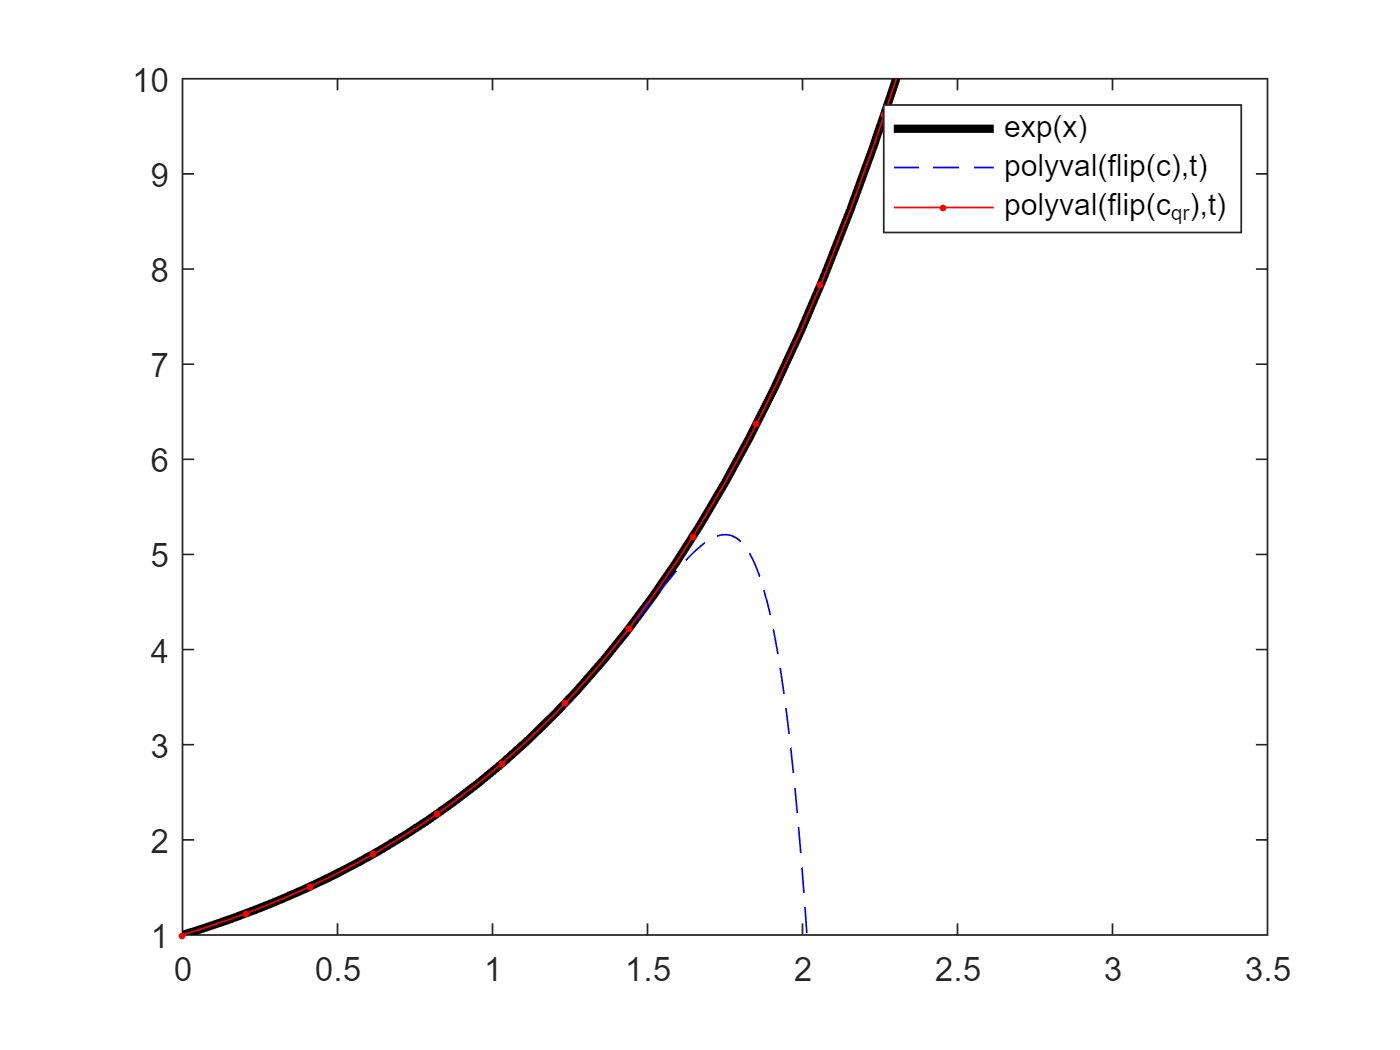

figure
fplot(f, 'k', 'LineWidth', 2.5)
hold on
axis([0 3.5 1 10])
fplot(P_ii, 'b--')
fplot(P_iv, 'r.-')
legend

(vii) Now let's try using  ${P}^{(ii)}(t)$ and ${P}^{(iv)}(t)$for *extrapolation*.  Produce a plot of $e^t$, ${P}^{(ii)}(t)$ and ${P}^{(iv)}(t)$over the interval $[0,2]$ on the same axes.  Can you tell them apart?

The QR decomposition determines the Taylor series approximation for exp(t) whereas the standard Least Squares method is not accurate.

This question suggests that algorithms that are equivalent on paper, may not perform equally well in a floating point environment.  Investigating these differences in detail is outside our juristiction in this unit, but we'll occasionally scratch at the surface.

## Software

### S1. QR factorisation

Write a MATLAB function `QR` (capitals, to distinguish it from MATLAB's inbuilt `qr` function) that takes as input an $m\times n$ matrix $A$ and performs the Gram-Schmidt process to return matrices $Q$ and $R$ such that $A = QR$.  The function should:

- output an **error **message if $A$ does not have full column rank.

Test your function out on various examples to check it works correctly.